% % % SVM classifier with training data, labels and test set
% tott = 15
% 
% s1 = size(train.t4,2);
% s2 = size(train.t9,2);
% data = [train.t4,train.t9];
% [U,S,V] = svd(data);
% v = S(1:tott,1:tott)*V(:,1:tott)';
% n = max(v(:));
% v = v/n;
% 
% Mdl = fitcsvm(v',[zeros(1,s1),ones(1,s2)]');
%   testdata = [test.t4,test.t9];
%  [U,S,V] = svd(testdata,'econ');
% v = S(1:tott,1:tott)*V(:,1:tott)';
% v = v/n;
% errortrain = resubLoss(Mdl)
%   testlabels = predict(Mdl,v');
%  correct = [zeros(1,size(test.t4,2)),ones(1,size(test.t9,2))]
%  error = (logical(testlabels')==logical(correct));
%   error = double(error);
% errortest = (size(error,2) - sum(error))/size(error,2)*100;
% 
% % %

% classify all numbers 
tott = 15;
[U,S,V] = svd(data,'econ');
v = S(1:tott,1:tott)*V(:,1:tott)';
n = max(v(:));
v = v/n;

Mdl = fitctree(v',labels)

Mdl =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
          NumObservations: 60000


  Properties, Methods


error = resubLoss(Mdl)

error = 0.0448


[U,S,V] = svd(datatest,'econ');
v = S(1:tott,1:tott)*V(:,1:tott)';
v = v/n;

error = resubLoss(Mdl)

error = 0.0448

[S,V,D] = svd(data,'econ')

S =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000         0    0.0000   -0.0000         0    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000         0   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000         0   -0.0000   -0.0000    0

V = 	1.0e+05 *

    3.8550         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.3087         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

D =     0.0043   -0.0004    0.0026   -0.0008    0.0049   -0.0026    0.0003   -0.0060    0.0004   -0.0030    0.0020   -0.0044    0.0004   -0.0119    0.0059   -0.0011    0.0081   -0.0020    0.0063   -0.0034    0.0005   -0.0014    0.0048   -0.0051    0.0017    0.0029   -0.0076   -0.0043    0.0032   -0.0033   -0.0027   -0.0010    0.0028    0.0029    0.0044    0.0058   -0.0020    0.0063   -0.0051    0.0111   -0.0067    0.0051   -0.0010    0.0031   -0.0045    0.0002   -0.0046    0.0029   -0.0013    0.0010
    0.0045    0.0071    0.0026    0.0062    0.0081   -0.0012    0.0022    0.0018    0.0007   -0.0021   -0.0043   -0.0001    0.0050   -0.0030   -0.0041   -0.0031   -0.0011   -0.0010    0.0012    0.0021    0.0045   -0.0018   -0.0001   -0.0000    0.0056    0.0051    0.0006   -0.0012    0.0092   -0.0022    0.0008    0.0025    0.0049    0.0030    0.0043    0.0026    0.0021   -0.0006   -0.0024   -0.0012    0.0072   -0.0029    0.0022    0.0055    0.0007   -0.0063    0.0099    0.0067   -0.0045    0

testlabels = predict(Mdl,v')

testlabels =      3
     7
     7
     5
     5
     7
     8
     8
     0
     4


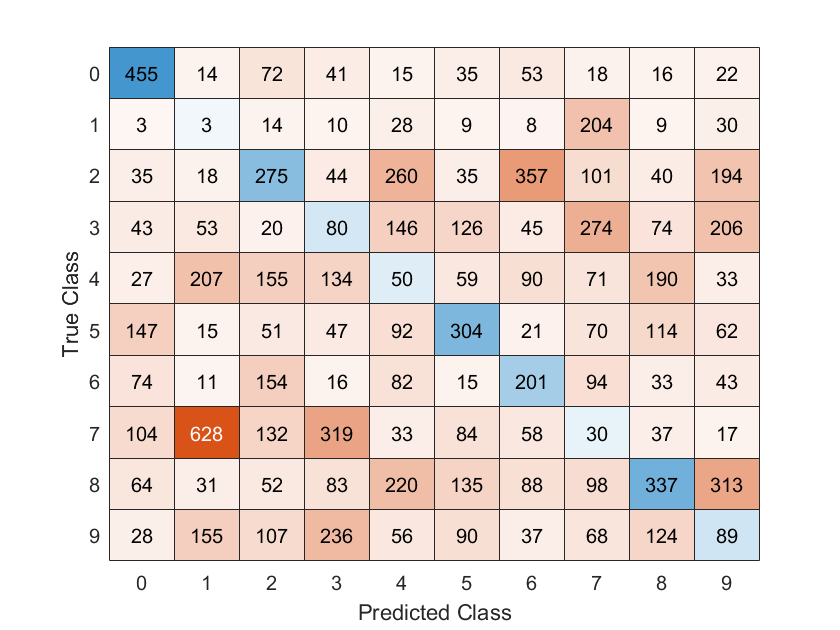

C = confusionmat(testlabels,labels2); 
confusionchart(C,{'0','1','2','3','4','5','6','7','8','9'})

cm.Title = 'Confusion matrix of SVM of MNIST dataset';

